# Main Subroutine for JRNY

% load training/test data (from DeepCFD https://github.com/mdribeiro/DeepCFD) 
    
    % dataset dimensions
    Ns = 981; Nc = 3; Nx = 172; Ny = 79;

    % check if data is already loaded
    if ~exist('dataX','var') && ~exist('dataY','var')

        % check if training data is already in .mat format
        if isfile('../data/dataX.mat') && isfile('../data/dataY.mat')
            dataX = load('../data/dataX.mat');
            dataY = load('../data/dataY.mat');
        else % otherwise read .pkl files (from https://zenodo.org/record/3666056/files/DeepCFD.zip?download=1)
            pickle = py.importlib.import_module('pickle'); % import pickle module (from python)
            X = py.open('../data/dataX.pkl','rb'); % open data
            Y = py.open('../data/dataY.pkl','rb');
            X_py = pickle.load(X); % returns numpy nd array
            Y_py = pickle.load(Y);
            X.close();
            Y.close();
            dataX = numpy2mat(X_py,Ns,Nc,Nx,Ny); % convert data to MATLAB array
            dataY = numpy2mat(Y_py,Ns,Nc,Nx,Ny); 
        end
    end

    % visualize random sample from dataset
    random = ceil(Ns*rand)

random = 786

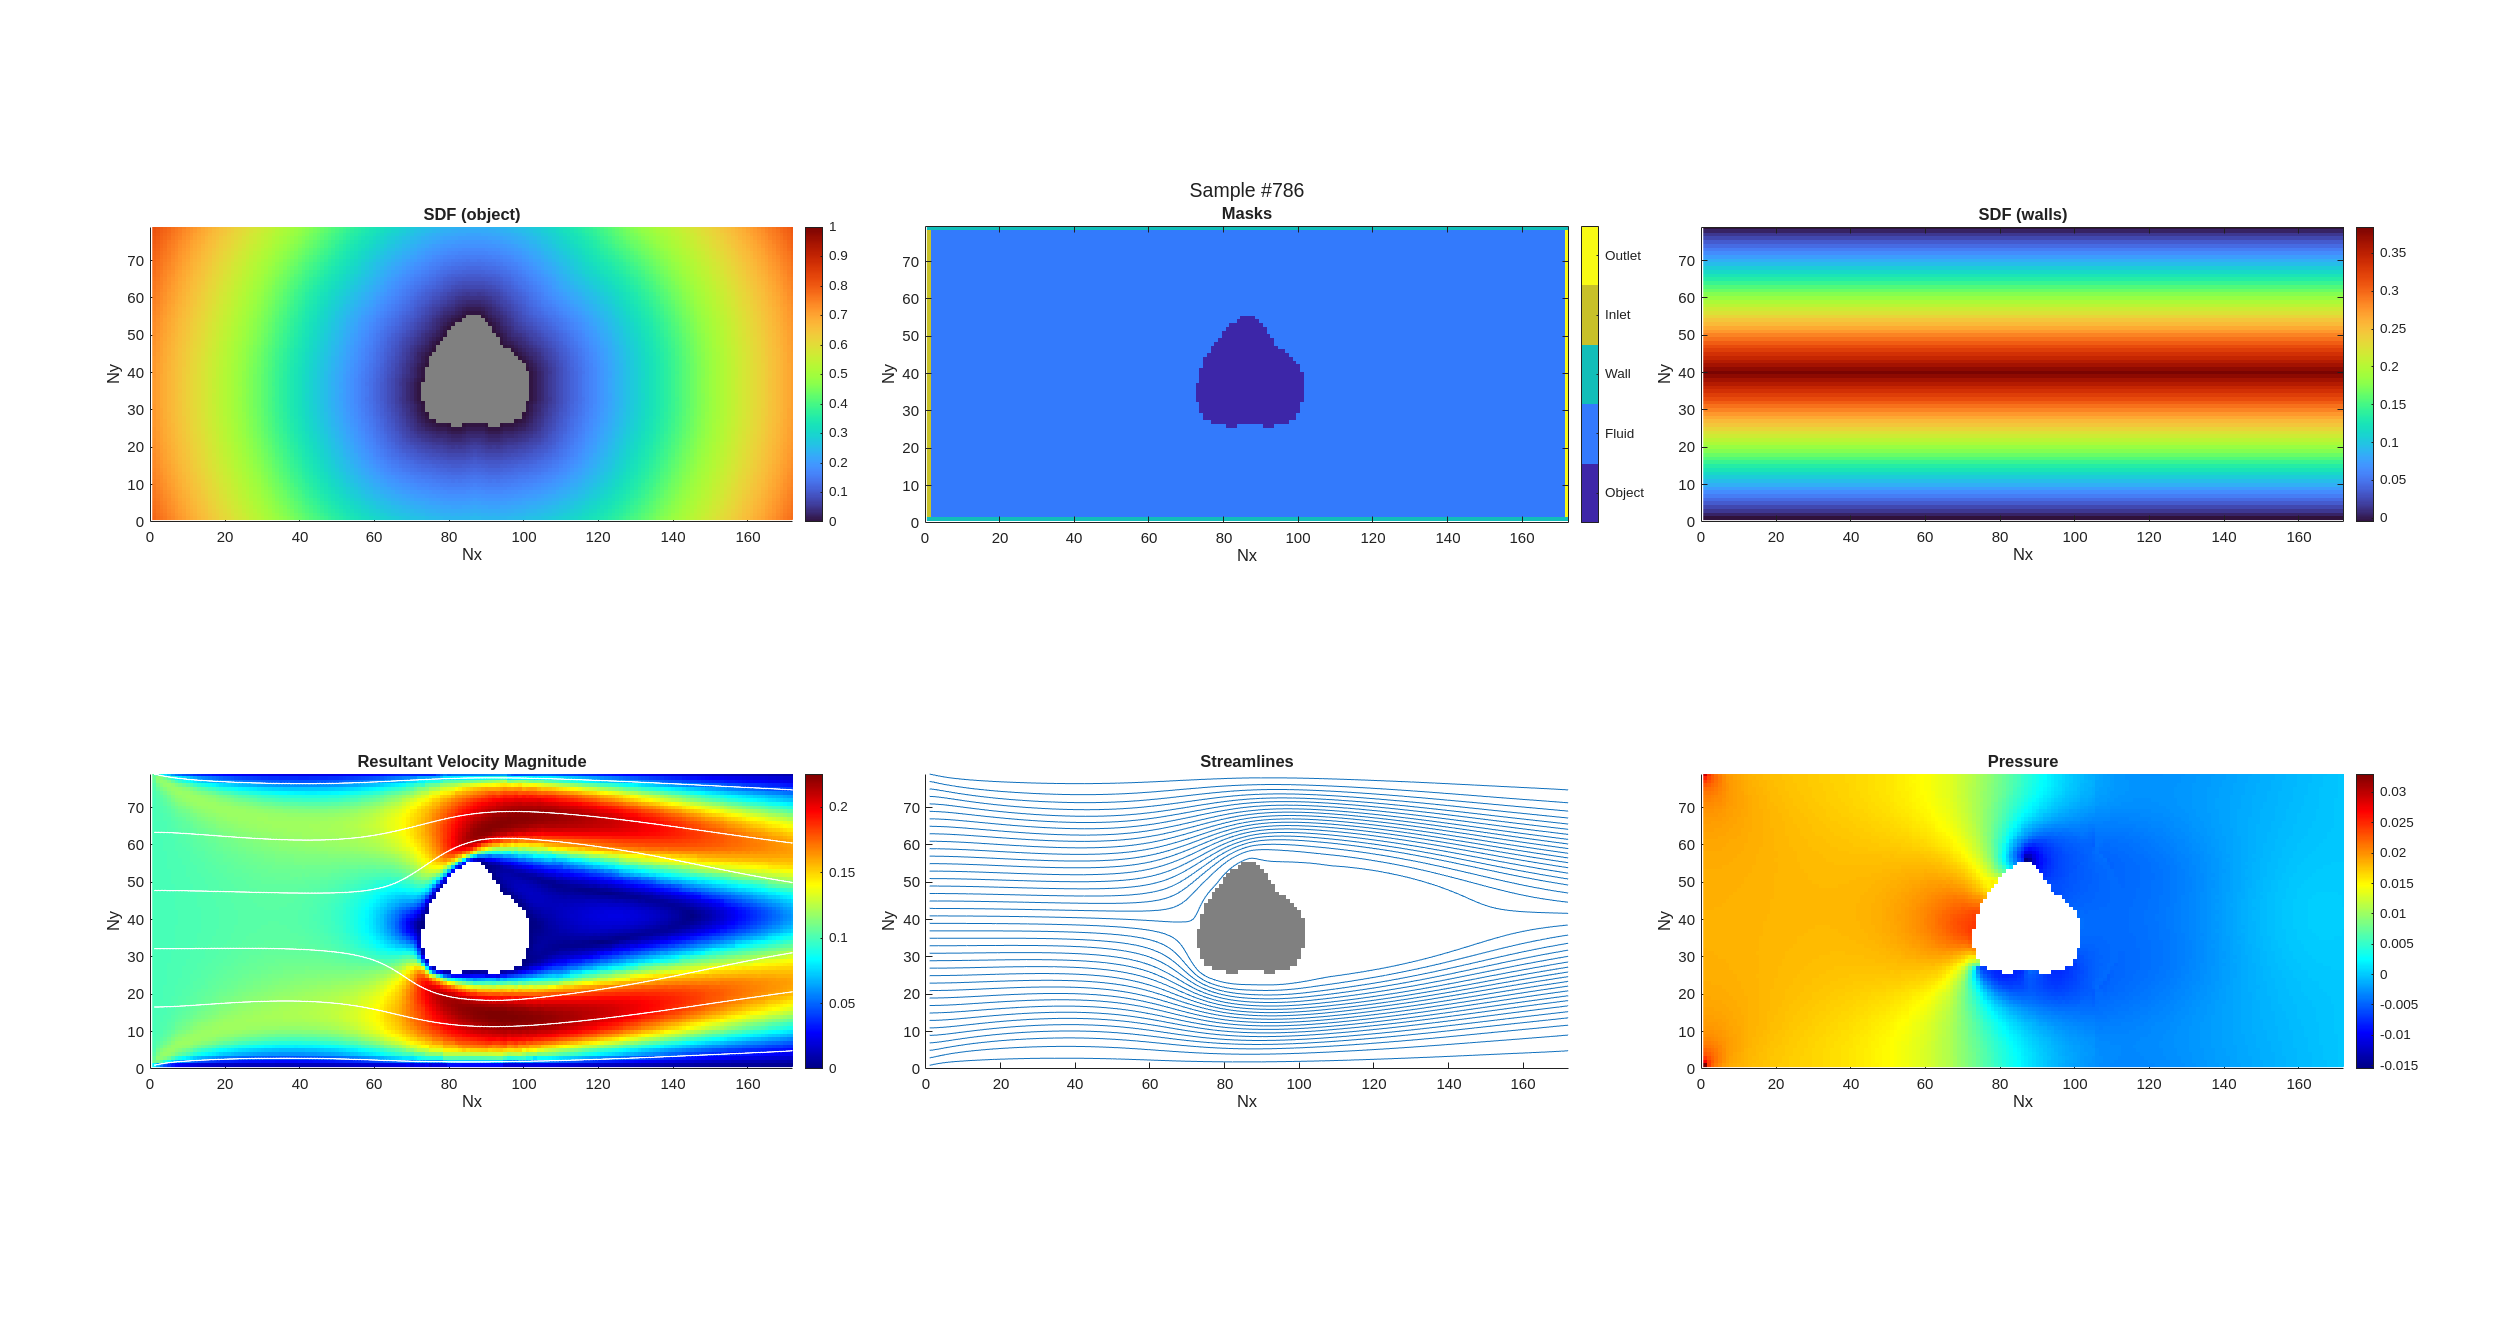

    plotXY(dataX,dataY,random,Nx,Ny);

The rest is a work in progress

% create neural network architecture

    % input and output size
    szIn = 1;
    szOut = 1;

    % number of hidden units
    numHidden = 128;

    % architecture
    layers = [ featureInputLayer...
                fullyConnectedLayer(numHidden)...
                tanhLayer...
                fullyConnectedLayer(numHidden)...
                tanhLayer...
                fullyConnectedLayer(szOut) ];

% train neural network

    % define hyperparameters
    numIter = 1000; % number of iterations;
    numEpochs = 50; % number of epochs

        % ADAM optimizer parameters (stochastic gradient descent with momentum)
        initialLR = 0.01; % initial learning rate
        mp = []; % mean
        vp = []; % variance

    % prepare data
    dataX = dlarray(dataX,'BCSS') % 
    dataY = dlarray(dataY,'BCSS') % format explained in https://arxiv.org/pdf/2004.08826

    % train neural network
    for i = 1:numIter
        [loss,grad] = dlfeval(@lossFcn,JRNY,dataX,dataY); % compute loss and gradients (in lossFcn.m)
        [JRNY,mp,vp] = adamupdate(JRNY,grad,mp,vp,i,initialLR); % update neural network
    end